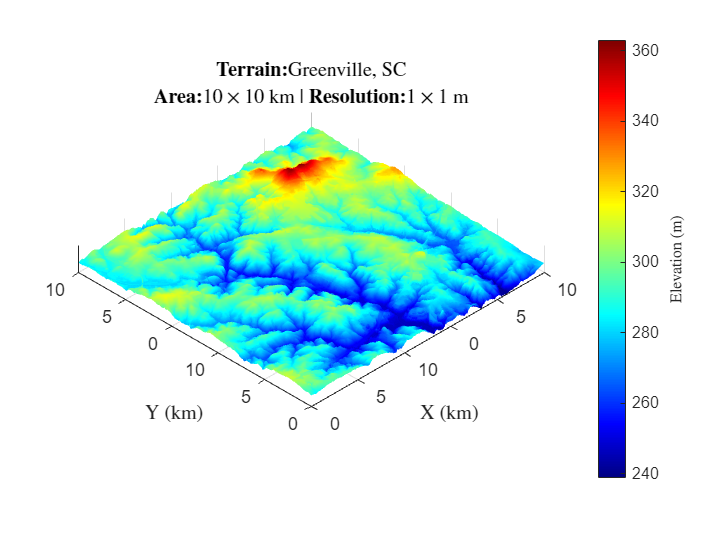

% Load DEM
[elevation,info] = readgeoraster("USGS_1M_17_x37y386_SC_SavannahPeeDee_2019_B19.tif",OutputType="double");

% Process DEM
res = 0.1; % Resolution for processing
Zinit = flipud(elevation); % Flip up-down
[Xinit,Yinit] = meshgrid(1:length(Zinit)); % Initial grid
[Xreal,Yreal] = meshgrid(1:(1/res):length(Zinit)); % Resolution-specific grid
Zreal = interp2(Xinit,Yinit,Zinit,Xreal,Yreal); % Interpolate elevation
surf(Xreal,Yreal,Zreal,EdgeColor="none"); % Generate surface

% Plot customization
colormap jet; % Define colormap
c = colorbar; % Add color bar
% Update X-ticks (km)
xtick_values = get(gca, 'XTick'); % Get current tick values
new_x_labels = num2str(xtick_values'/1000); % Calculate new labels
set(gca, 'XTickLabel', new_x_labels); % Set the new tick labels
% Update Y-ticks (km)
ytick_values = get(gca, 'YTick'); % Get current tick values
new_y_labels = num2str(ytick_values'/1000); % Calculate new labels
set(gca, 'YTickLabel', new_y_labels); % Set the new tick labels
% Update Z-ticks (m)
zticks([floor(min(min(Zreal))), ceil(max(max(Zreal)))])
% Define title, subtitle, and labels
title('\textbf{Terrain:} Greenville, SC', Interpreter='latex');
subtitle('\textbf{Area:} 10$\times$10 km | \textbf{Resolution:} 1$\times$1 m', Interpreter='latex');
c.Label.Interpreter = 'latex';
c.Label.String = 'Elevation (m)';
xlabel('X (km)', Interpreter='latex')
ylabel('Y (km)', Interpreter='latex')
% zlabel('Z (m)', Interpreter='latex')
% Set aspect ratio and viepoint
pbaspect([1 1 0.1]); % Set aspec ratio
view(-45, 35); % Set the viewpoint (azimuth, elevation)